Controlador PID 

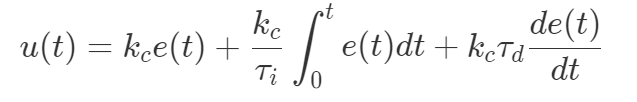

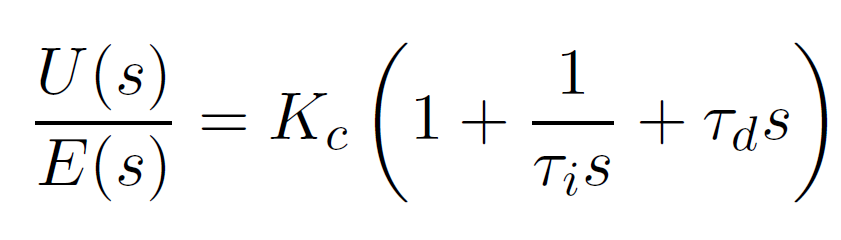

clc; clear; close all
% ******************** + Parametros del sistema  + ********************
 % Tiempo de muestreo
T = 0.01;                
% modelo del sistema en su funcion de transferencia
s = tf('s');
G = 4.228 / ((s+0.5) * (s^2 + 1.64*s + 8.456))     % G1 de ejemplo

G =
 
               4.228
  --------------------------------
  s^3 + 2.14 s^2 + 9.276 s + 4.228
 
Continuous-time transfer function.



%G = 27 / ((s+1)*(s+3)^3);                          % G2 de ejemplo
%G = exp(-0.5*s)/((s+1)^2)                          % G3 de ejemplo

% modelo del sisteam en espacio de estados
H = c2d(G,T);
[num,den] = tfdata(H,'v');
[A, B, C, D] = tf2ss(num,den)

A =     2.9779   -2.9567    0.9788
    1.0000         0         0
         0    1.0000         0


B =      1
     0
     0


C = 	1.0e+-5 *

    0.0701    0.2788    0.0693


D = 0


% *******************************  ZN  **************************************
Ku = 3.665;
Tu = 2.06;
% Ku = 5.12;
% Tu = 2.06;
% Ku = 4.68;
% Tu = 3.28;
% ********************* + Parametros del controlador + **********************
Kp = 0.6 * Ku

Kp = 2.1990

Ki = 0.6 * Ku * 2 / Tu ;  % Ki = (Kp/Ti) ; Ti = Tu/2
Kd = 0.6 * Ku * Tu /  8;  % Kd = (Kp*Td) ; Td = Tu/8
Ti = Kp/Ki

Ti = 1.0300

Td = Kd/Kp

Td = 0.2575

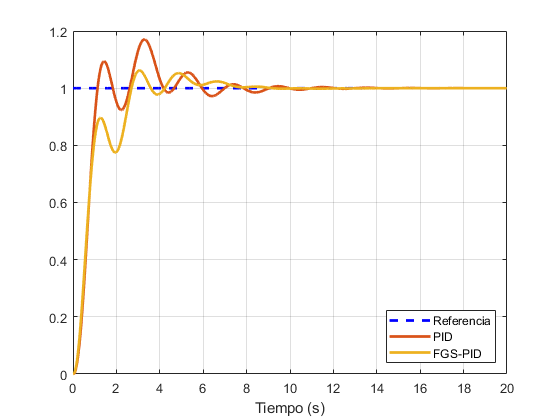

% *********************** FSG *****************************************

fis = readfis('fuzzy_control');

Kpmin = 0.533 * Kp; % 0.32 * Ku;
Kpmax =    1  * Kp; % 0.60 * Ku;
Kdmin = 1.067 * Kd; % 0.08 * Ku * Tu;
Kdmax =     2 * Kd; % 0.15 * Ku * Tu;
Kimin =  0.01 * Ki;
Kimax =  0.85 * Ki;
% ************************ + Lazo de simulacion + *************************
ts = 20;                                % Tiempo de simulacion
t = 0 : T : ts-T;                       % Vector de tiempo
Ns = round(ts/T);                       % # muestras por simulacion
theta = G.OutputDelay;                  % Delay de la funcion continua
N = floor(theta/T);                     % N Delays

e(N+1) = 0;                             % Condiciones inciales
e(N+2) = 0;                             % Condiciones inciales

u(N+2) = 0;                             % Señal de control (inicializacion)
y(N+2) = 0;                             % Señal de Salida  (inicializacion)
x(:,N+2) = zeros(1,length(C));          % vector de estado (inicializacion)

r = ones(1,Ns);                         % Referencia r = 1

e_acum = 0;
for k = N+2 : Ns
    y(k) = C*x(:,k) ;
    e(k) = r(k) - y(k);
    e_acum = e_acum + e(k);
    delt_e = e(k) - e(k-1);
    u(k) = Kp * e(k)  + Ki * T * e_acum + Kd * delt_e / T;
    x(:,k+1) = A*x(:,k) + B*u(k);
end
y1 = y;

e(N+1) = 0;                             % Condiciones inciales
e(N+2) = 0;                             % Condiciones inciales

u(N+2) = 0;                             % Señal de control (inicializacion)
y(N+2) = 0;                             % Señal de Salida  (inicializacion)
x(:,N+2) = zeros(1,length(C));          % vector de estado (inicializacion)

e_acum = 0;
for k = N+2 : Ns
    y(k) = C*x(:,k) ;            % vector de salida
    e(k) = r(k) - y(k);          % error
    e_acum = e_acum + e(k);      % error acumulado
    delt_e = (e(k) - e(k-1));    % diferencia del error
    %  -------------Controlador FGS-PID -----------------
    output= evalfis(fis,[e(k) delt_e]);
    Kpp = output(1);
    Kdp = output(2);
    Kip = output(3);
    Kp = (Kpmax - Kpmin) * Kpp + Kpmin;
    Kd = (Kdmax - Kdmin) * Kdp + Kdmin;
    Ki = (Kimax - Kimin) * Kip + Kimin;
    u(k) = Kp * e(k)  + Ki * T * e_acum + Kd * delt_e / T; 
    % ----------------------------------------------------
    x(:,k+1) = A*x(:,k) + B*u(k); % vector de estados
end

% **************************** Graficas *******************************
figure(1)
plot(t, r,'b--',t,y1,t,y, 'LineWidth', 2); grid on
xlabel('Tiempo (s)')
legend({'Referencia', 'PID','FGS-PID'},'Location','southeast')

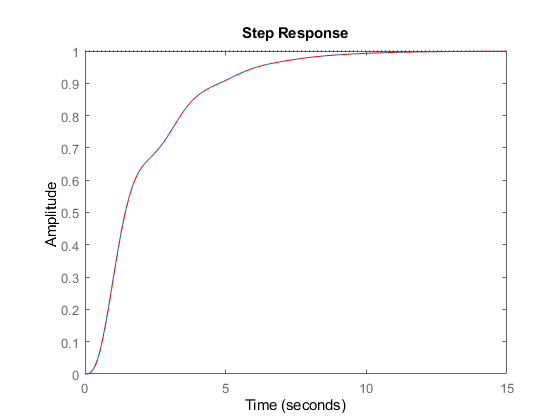

% *************************** Graficas otras ********************************
figure(2)
step(G)
hold on
step(H,'r--')
hold off

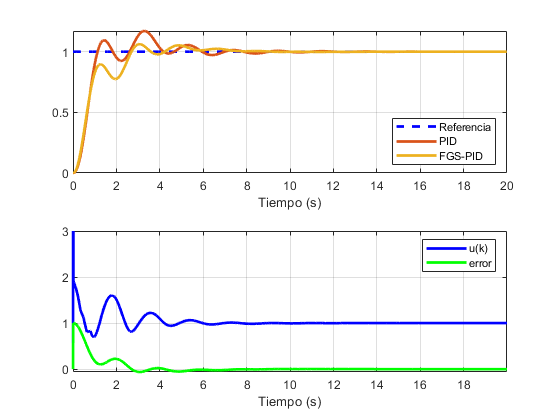


figure(3)
subplot(2,1,1)
plot(t, r,'b--',t,y1,t,y, 'LineWidth', 2); grid on
xlabel('Tiempo (s)')
legend({'Referencia', 'PID','FGS-PID'},'Location','southeast')

subplot(2,1,2)
plot(t, u,'b',t,e,'g', 'LineWidth', 2); grid on
legend('u(k)','error');
xlabel('Tiempo (s)')
axis([-inf inf -inf 3])